# Exakte Numerische Lösung

### 1. DGL und Referenzperiode

Zur Bestimmung der Periodendauer für beliebige Anfangsauslenkungen wird die nichtlineare Bewegungsgleichung des Pendels numerisch gelöst:


$$\ddot{\varphi} (t)+\frac{g}{l}\sin \left(\varphi (t)\right)=0$$


Im Gegensatz zur Kleinwinkelnäherung bleibt der Sinus-Term erhalten, wodurch die Periodendauer von der Anfangsauslenkung $\varphi_0$ abhängt. Die Differentialgleichung 2. Ordnung wird als System 1. Ordnung geschrieben mit: 


$$\begin{array}{l}
y_1 =\varphi ,~~~~y_2 =\dot{\varphi} \\
{\dot{y} }_1 =y_2 ,~~~~{\dot{y} }_2 =-\frac{g}{l}\,\sin \left({\;y}_1 \right)
\end{array}$$


Wie bei Aufgabe 1 verwendet man als Anfangsbedingungen (in Ruhe, losgelassenes Pendel)


$$\varphi (0)=\varphi_0 ,~~~~\dot{\varphi} (0)=0$$


clear; clc; close all;

g = 9.81;
s = 0.1;
l = g/s;
omega = sqrt(g / l);
T0 = 2*pi / omega;
targets = [0.01 0.05 0.10 0.50 1.00];  

### 2. Zielwinkel für feste Abweichungen ( 1%, 5%, 10%, 50%, 100%)

Zusätzlich werden die Anfangsauslenkungen ermittelt, bei denen die Periodendauer um p größer als $T_0$ ist. Dazu wird die Nullstelle der Funktion:


$$F(\varphi_0 )=\frac{T(\varphi_0 )}{T_0 }-(1+p)$$



$$\[
T(\varphi_0) = (1+p)\,T_0
\]
$$


im Winkelintervall [1°, 170°] numerisch bestimmt (z. B. mit `fzero`)

phi0_found = NaN(size(targets));

% Schleife über alle geforderten Abweichungen, numel = Anzahl (5)
for j = 1:numel(targets)
    % Wert rauspicken
    p = targets(j);
    % Funktion definieren, deren Nullstelle null wird.
    % T_exact liefert Periodendauer, T_0 normiert. Man will den wert finden
    % wo F(phi) = 0 ist.
    F = @(phi0) T_exact(phi0,g,l,T0)/T0 - (1+p);
    % Intervall von a bis b (hier wird gesucht)
    a = deg2rad(1);
    b = deg2rad(170);
    % fzero sucht wo im Intervall F(phi) = 0 gilt
    phi0 = fzero(F, [a b]);
    phi0_found(j) = rad2deg(phi0);
    % Periodendauer bestimmen
    Tex = T_exact(phi0,g,l,T0);
    fprintf("%3.0f%%  = %9.4f Grad  T = %.8f s\n", 100*p, rad2deg(phi0), Tex);
end

  1%  =   22.8764 Grad  T = 20.06786830 s
  5%  =   50.1603 Grad  T = 20.86263536 s
 10%  =   69.3748 Grad  T = 21.85609418 s
 50%  =  132.6853 Grad  T = 29.80376480 s
100%  =  159.7586 Grad  T = 39.73835306 s


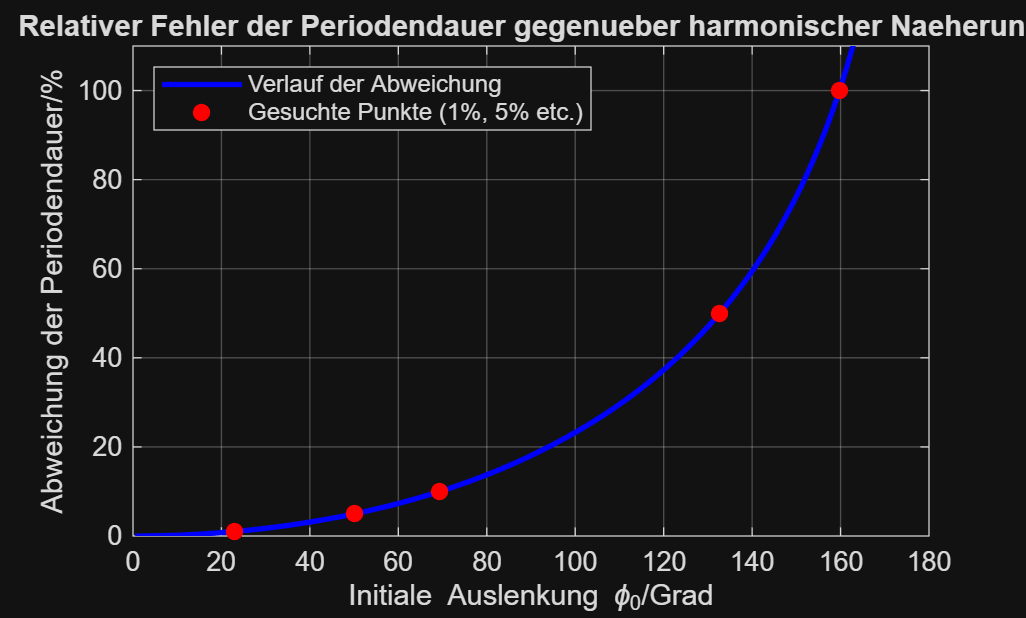


%------------- Für den Plot---------------

phi0_deg = linspace(0.5, 170, 250);     % beliebige Auslenkungen (nicht bis 180)
phi0_rad = deg2rad(phi0_deg);

Tex_list = NaN(size(phi0_rad));
dev_list = NaN(size(phi0_rad));

for i = 1:numel(phi0_rad)
    Tex_list(i) = T_exact(phi0_rad(i), g, l, T0);
    dev_list(i) = (Tex_list(i)/T0 - 1) * 100;  % Abweichung in %
end


% --- Visualisierung 1: Abweichung vs. Auslenkung ---
figure('Name', 'Abweichung der Periodendauer');
plot(phi0_deg, dev_list, 'b-', 'LineWidth', 2); hold on;

% Markiere die gefundenen Punkte
plot(phi0_found, targets * 100, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);

% Beschriftung
xlabel('Initiale Auslenkung \phi_0/Grad');
ylabel('Abweichung der Periodendauer/%');
title('Relativer Fehler der Periodendauer gegenueber harmonischer Naeherung');
grid on;
xlim([0 180]);
ylim([0 110]); % Begrenzung fuer bessere Sichtbarkeit bis 100%

% Legende dynamisch erstellen
legend_entries = {'Verlauf der Abweichung', 'Gesuchte Punkte (1%, 5% etc.)'};
legend(legend_entries, 'Location', 'NorthWest');

### 2. Bestimmung der Periodendauer über ein Event

Die Periodendauer wird nicht über Peaks, sondern über einen bestimmten Phasenpunkt bestimmt, den den ersten Nulldurchgang. Da das Pendel bei t = 0 startet, ist dieser Zeitpunkt ein Viertel der Periodendauer: 


$$t_q =\frac{T}{4}~~\Rightarrow ~~T=4\,t_q$$


### 3. Abweichung zur Kleinwinkelnäherung

Als Refernez wurde die Kleinwinkel-Periodendauer genommen:


$$T_0 =\frac{2\pi }{\omega }$$


% aus Anfangsauslenkung phi0 die exakte Periodendauer berechnen
function T = T_exact(phi0,g,l,T0)
    % Anfangszustand
    y0 = [phi0; 0];
    % anonyme func für DGL
    exact_func = @(t,y) [y(2); -(g/l)*sin(y(1))];
    % Eventfunktion fürs
    opts = odeset('Events',@event_zero_down);
    % max. Simulationszeit
    tmax = 100*T0;
    [t, y, te, ye, ie] = ode45(exact_func, [0 tmax], y0, opts);
    tq = te(1);
    % Zeitpunkt des ersten Events (x -> -) = Viertelperiode daher mal 4
    T  = 4*tq;
end

function [value,isterminal,direction] = event_zero_down(~,y)
    value = y(1); % Event trifft auf wenn value = 0 also phi = 0
    isterminal = 1; % Integration stoppen
    direction = -1; % wenn value von + auf - geht
end